# Assignment #2: ECMS

**Read the following instructions carefully. **

This live script serves as a template for your second assignment. You must replace all the text in the template with your own report, filling in each section as appropriate. Remove these instructions from your final report as well.

Consider the empty code sections as a guideline: you can add more or remove them. However, please note that all local function definitions (such as the function for your torque controller) must be declared at the end of the live script, or they won't work.

In order to get your assignment graded, you must upload the following files:

- Your assignment livescript in .mlx format

- Your assignment in pdf format.

- Your results in a .mat file

- Any other function/file needed to run this live script.

You must compress all these files in a .zip folder. You must name the folder "group" + [your group number with double digits], e.g. "group01.zip", "group12.zip". Make sure you dont type "group1".

Upload all files in the *Assignment 02* activity on the course's Moodle website, which you can access from the *Portale della Didattica*. Only one person for each group should upload the folder; please avoid multiple uploads of the same assignment.

**Grading**

For this report, you will evaluated based on the following criteria:

- Whether the controller and bisection algorithm work as intended or not.

- Your description and explanation, in plain text, of your implementation of the ecms controller and of the bisection algorithm.

- Your analysis of the controller's performance, supported by the appropriate plots and results. You should at least use the post-processing tools we provided to you; if you find them inadequate, you can develop your own or modify them to illustrate additional information.

- The quality of the code. This includes general code readability, approriate usage of clear and succint code comments, usage of meaningful and unambiguous variable names, etc.

## Group information

Group number: 09

Students:

- Nozima Yakubova, s344733

- Nicolo Ferruggia, s349151

- Ulugbek Rakhmatullaev, s330568

## Load the cycle and vehicle data

Load data and other preliminaries. Remember to scale the vehicle data.

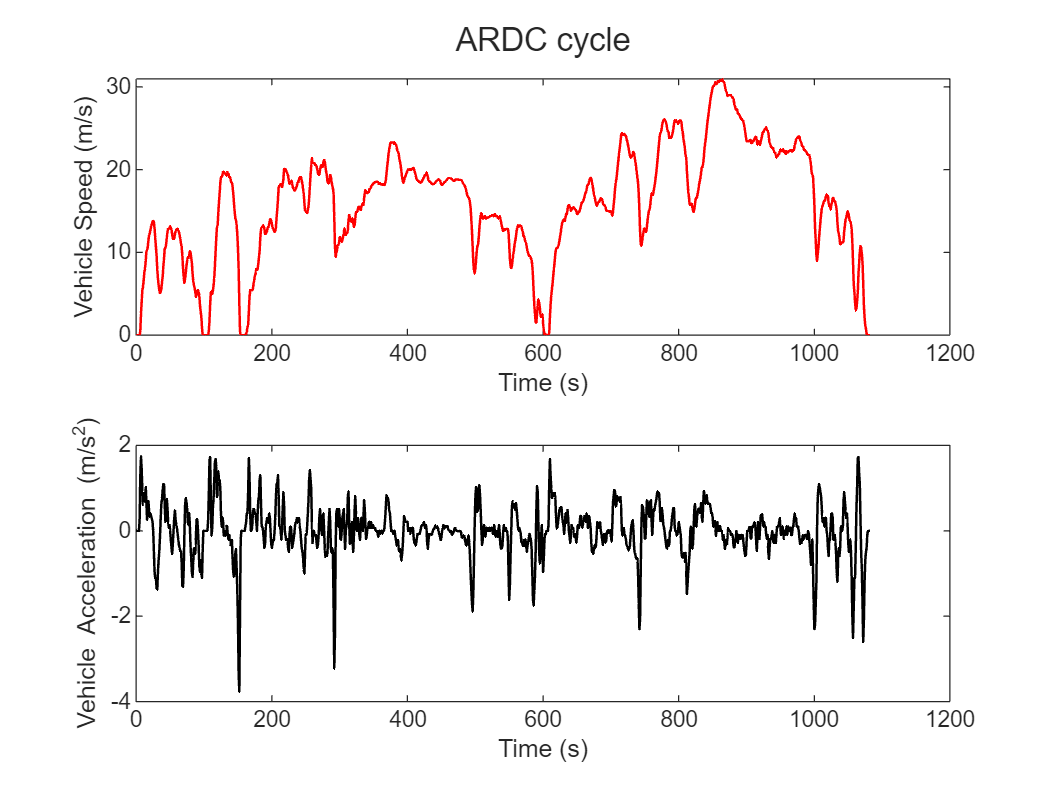

clc; clear; close all; % Housekeeping

% Add the folders to the Path
addpath("utilities");
addpath("models");
addpath("data");

mission = load("ARDC.mat");         % Load the ARDC cycle
time = mission.time_s;              % [s]
vehSpd = mission.speed_km_h./3.6;   % [m/s]
vehAcc = mission.acceleration_m_s2; % [m/s^2]

% Create the figure of ARDC cycle
t = tiledlayout(2,1); 

nexttile(1)
% Plot the vehicle speed
plot(time,vehSpd, LineStyle="-", LineWidth=1, Color='r');
xlabel("Time (s)");
ylabel("Vehicle Speed (m/s)");

nexttile(2)
% Plot the vehicle acceleration
plot(time, vehAcc, LineStyle="-", Color='k', LineWidth=1);
xlabel("Time (s)");
ylabel("Vehicle Acceleration (m/s^2)");
title(t, "ARDC cycle");

% Load vehicle data
veh = load(fullfile("data", "vehData.mat"));

% Scale vehicle data according to the group parameters
motPwr = 70000; % [W]
engPwr = 66000;  % [W]
battEnrg = 1260;  % [Wh]
veh = scaleVehData(veh, motPwr, engPwr, battEnrg);

## Equivalence factor calibration

Develop a bisection algorithm to calibrate the equivalence factor in order to ensure charge-sustaining operation. The terminal SOC deviation should be within 0.01, i.e. your terminal SOC should be $0.59 < \sigma_\mathrm{f} <0.61$.

Describe your calibration algorithm, by using code comments and/or this text section. **You will not get full marks if your function is not documented appropriately.**

SOC(1)=0.6;
for n = 1:length(time)
   [engSpd(n), engTrq(n)] = ecmsControl(SOC(n), vehSpd(n), vehAcc(n), veh);
   [SOC(n+1), fuelFlwRate(n), unfeas(n), prof(n)] = hev_model(SOC(n), [engSpd(n), engTrq(n)], [vehSpd(n), vehAcc(n)], veh);
end


## Run a simulation with the calibrated equivalence factor

Run a simulation with the calibrated equivalence factor, so you can inspect the behavior of the charge-sustaining ECMS controller.

## Save results

Save the time profiles, fuel consumption (in kg), fuel economy (in l/100km), final SOC and calibrated equivalence factor in a mat-file named `results.mat`. Make sure they are named exactly as in the following code section.

If you have not done it before, use this code to convert your time profiles into scalar structures and pack them into a parent structure:

% Transform the non-scalar struct containing time profiles into scalar
% structs; this makes their manipulation easier.
engPrf = structArray2struct(engPrf);

Unrecognized function or variable 'engPrf'.

emPrf = structArray2struct(emPrf);
battPrf = structArray2struct(battPrf);
vehPrf = structArray2struct(vehPrf);
% Pack profiles into a single structure
prof.engPrf = engPrf;
prof.emPrf = emPrf;
prof.battPrf = battPrf;
prof.vehPrf = vehPrf;

You can move this code wherever you need.

Finally, use this code to save your results (based on your calibrated equivalence factor)

% Store results
save("results.mat", "prof", "fuelConsumption", "fuelEconomy", "finalSOC", "eqFactor")

- `prof`, `fuelConsumption` , `fuelEconomy`, `finalSOC` are as in Lab 01.

- `eqFactor` is the calibrated equivalence factor.

## Controller analysis

Analyze the behaviour and the performance of the calibrated ECMS controller; support your analysis with relevant plots. You can use the postprocessing functions we provided and/or produce your own plots.

## The ECMS controller

Describe your implementation of the ecms controller, by using code comments and this text section. **You will not get full marks if your function is not documented appropriately.**

In particular:

- Describe all inputs and outputs and why you need them.

- Name/briefly describe any other parameter that you create.

- Clearly explain in plain text how your controller works.

Remember that your ECMS must enforce the condition that the SOC never exceeds the following upper and lower thresholds:

- $\sigma_\mathrm{up} = 0.8$,

-  $\sigma_\mathrm{lo} = 0.4$.

Also, not that this section *must* come at the end of the live script, or your function will not be properly recognized by the preceding part of the script. Local functions, including this one and any other function that you may want to define, must always be defined at the end of your script.

function [engSpd, engTrq] = ecmsControl(SOC, vehSpd, vehAcc, veh)
s = 2;

engSpd_values = linspace(veh.eng.idleSpd, veh.eng.maxSpd, 9);
engSpd_values = [0,engSpd_values];
maxEngTrq = max(veh.eng.maxTrq.Values);
engTrq_values = linspace(0, maxEngTrq, 10);

for i = 1:length(engSpd_values)
    for j = 1:length(engTrq_values)
        [SOC(i,j+1), fuelFlwRate(i,j), unfeas(i,j)] = hev_model(SOC, [engSpd_values(i), engTrq_values(j)], [vehSpd, vehAcc], veh);
    end
end

fuelFlwRate_eq = fuelFlwRate + s * (veh.batt.nomEnergy/veh.eng.fuelLHV) * SOC(1:10,1:10) + unfeas*1e5;

[min_FFR, idx] = min(fuelFlwRate_eq, [], 'all');
[raw, col] = ind2sub(size(fuelFlwRate_eq), idx);

engSpd = engSpd_values(raw);
engTrq = engTrq_values(col);
end